Import Exoplanets

exoplanets = readtable('exoplanets.txt');

Part A

[minimum, ind] = min(exoplanets.Distance);
closestname = exoplanets.Name(ind)

closestname = 1×1 cell array
    {'alf Cen B b'}


Part B

numhabitable = sum(exoplanets.Habitable)

numhabitable = 54

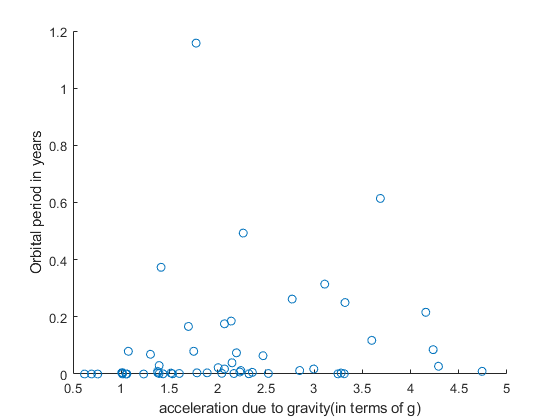

m = exoplanets.Mass(exoplanets.Habitable == 1);
r = exoplanets.Radius(exoplanets.Habitable == 1);
a = exoplanets.Orbit(exoplanets.Habitable == 1);
[pT, pg] = planet(m , r, 1, a);
scatter(pg, pT)
xlabel("acceleration due to gravity(in terms of g)")
ylabel('Orbital period in years')

Part C

methods = exoplanets.Method

methods = 2637×1 cell array
    {'imaging'        }
    {'primary transit'}
    {'imaging'        }
    {'imaging'        }
    {'imaging'        }
    {'imaging'        }
    {'imaging'        }
    {'imaging'        }
    {'imaging'        }
    {'imaging'        }
    {'imaging'        }
    {'imaging'        }
    {'imaging'        }
    {'imaging'        }
    {'radial velocity'}
    {'radial velocity'}
    {'radial velocity'}
    {'radial velocity'}
    {'imaging'        }
    {'radial velocity'}
    {'radial velocity'}
    {'radial velocity'}
    {'radial velocity'}
    {'radial velocity'}
    {'radial velocity'}
    {'radial velocity'}
    {'radial velocity'}
    {'radial velocity'}
    {'radial velocity'}
    {'radial velocity'}


mostcommon = mode(methods)

mostcommon = 'imaging'

percent = 100 * (sum(exoplanets.Method == mostcommon)/numel(exoplanets.Method))

Undefined operator '==' for input arguments of type 'cell'.